# LAB 1 - ELEMENTS OF AIRPLANE PERFORMANCE (I)

clear
close all
clc

## POLAR GRAPH

### Experimental  polar data

load("MB339_polar.mat")
[CL_min,~] = min(CL);
[CL_max,idx_CL_max] = max(CL);
len = 1e2;
CL_domain = linspace(CL_min,CL_max,len);

### Linear interpolation 

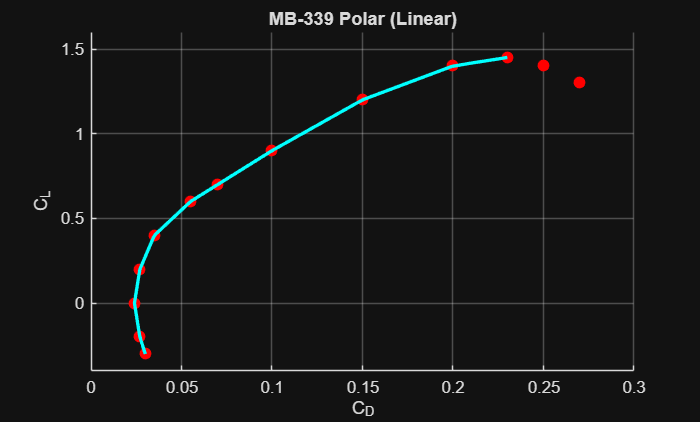

figure
scatter(CD,CL,50,"red","filled")
title('MB-339 Polar (Linear)')
xlabel("C_D")
ylabel("C_L")
grid on
hold on

CD_interp1 = interp1(CL(1:idx_CL_max),CD(1:idx_CL_max),CL_domain);
plot(CD_interp1,CL_domain,"c",LineWidth=2)

### Spline

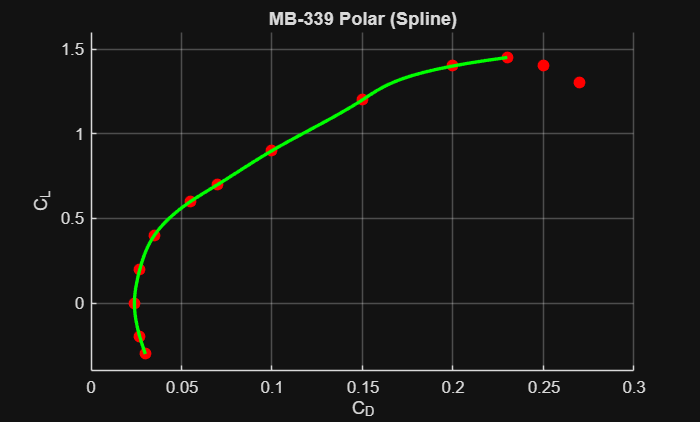

figure
scatter(CD,CL,50,"red","filled")
title('MB-339 Polar (Spline)')
xlabel("C_D")
ylabel("C_L")
grid on
hold on

CD_spline = spline(CL(1:idx_CL_max),CD(1:idx_CL_max),CL_domain);
plot(CD_spline,CL_domain,"g",LineWidth=2)

### Quadratic interpolation

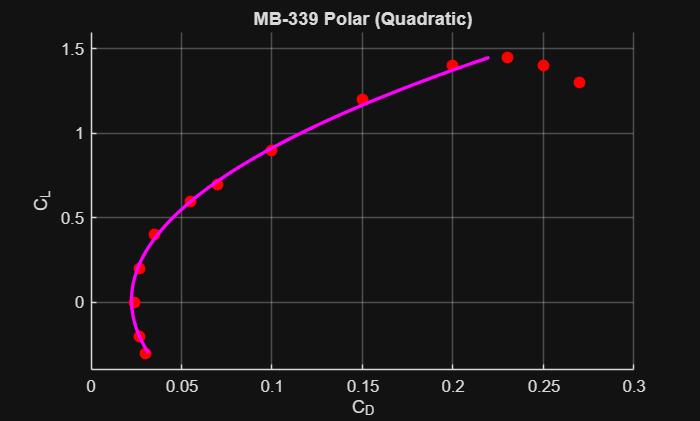

figure
scatter(CD,CL,50,"red","filled")
title('MB-339 Polar (Quadratic)')
xlabel("C_D")
ylabel("C_L")
grid on
hold on

CD_quadratic_coeff = polyfit(CL(1:idx_CL_max),CD(1:idx_CL_max),2);
CD_quadratic = polyval(CD_quadratic_coeff,CL_domain);
plot(CD_quadratic,CL_domain,"m",LineWidth=2)

### Comparison

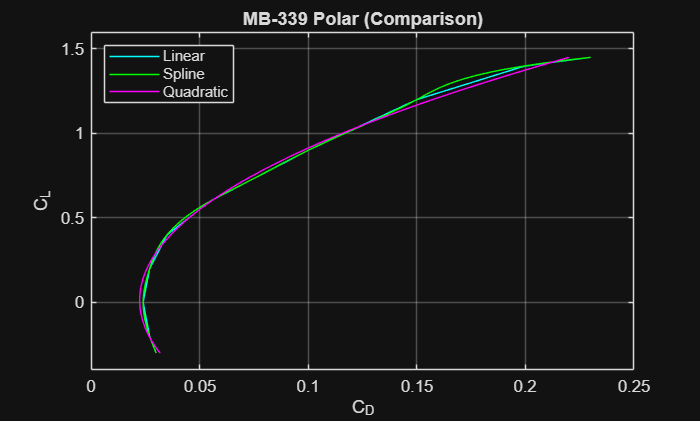

figure
plot(CD_interp1,CL_domain,"c")
grid on
hold on
plot(CD_spline,CL_domain,"g")
plot(CD_quadratic,CL_domain,"m")
title('MB-339 Polar (Comparison)')
xlabel("C_D")
ylabel("C_L")
legend('Linear','Spline','Quadratic',Location='northwest')

## THRUST

### Experimental data

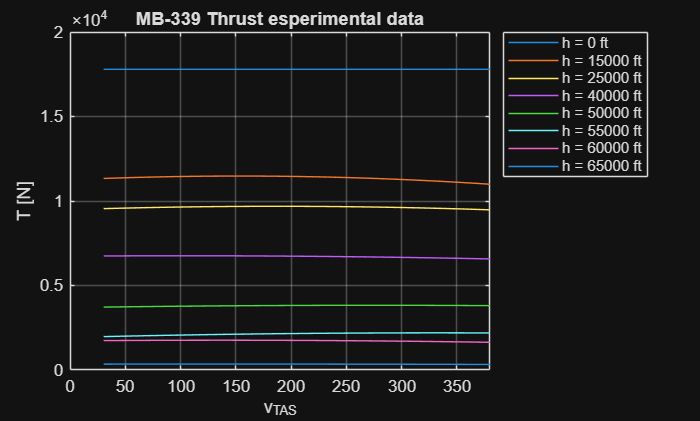

load("MB339_thrust.mat")
[n,m] = size(T);
v_T_domain = linspace(min(V),max(V),len);
T_h = zeros(n,len);
T_coeff_h = zeros(n,3);

for i=1:n
    T_coeff_h(i,:) = polyfit(V,T(i,:),2);
    T_h(i,:) = polyval(T_coeff_h(i,:),v_T_domain);
end

figure
plot(v_T_domain,T_h)
grid on
title('MB-339 Thrust esperimental data')
xlabel('v_{TAS}')
ylabel("T [N]")
xlim([0, inf])
ylim([0, 20000])
legendLabels = compose('h = %g ft', h); 
legend(legendLabels, 'Location', 'northeastoutside');

Jet engines thrust is then analytically assumed as T=T_0(rho/rho_0)^A, constant with speed. In this case A is given, A = 0.75,

### Analytical model

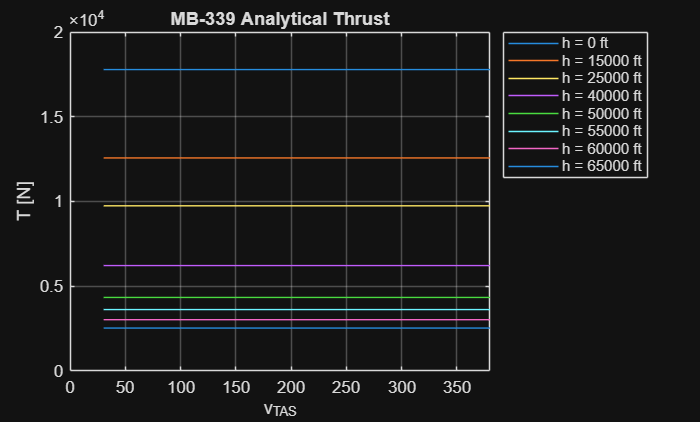

A = 0.75;
[~,~,~,rho_h] = atmosisa(h.*unitsratio('m', 'ft'));
rho_0 = max(rho_h);
T_0 = mean(T(1,:));
T_rho = @(rho) (rho./rho_0).^A * T_0;

figure
plot(v_T_domain,T_rho(rho_h)'.*ones(len,1))
grid on
title('MB-339 Analytical Thrust')
xlabel('v_{TAS}')
ylabel("T [N]")
xlim([0, inf])
ylim([0, 20000])
legendLabels = compose('h = %g ft', h); 
legend(legendLabels, 'Location', 'northeastoutside');

## PENAUD DIAGRAMS

W = 61000; % weight, [N]
S = 19.3; % wing area, [m^2]
k = CD_quadratic_coeff(1); % induced drag coefficient [-]
CD0 = CD_quadratic_coeff(3); % parasite drag coefficient [-]
wing_load = W/S;
v_stall_h_fun = @(rho) sqrt(2*wing_load/rho/CL_max);
v_stall_h0 = v_stall_h_fun(rho_0);
v_guess_h0 = 400;
v_D_domain_h0 = linspace(v_stall_h0,v_guess_h0,len);

### Linear interpolation

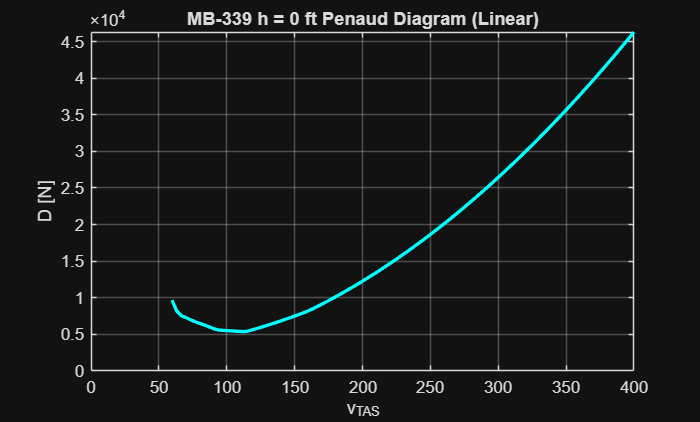

D_interp1_h = @(v,rho) 1/2 * rho_0 * v.^2 * S .* interp1(CL(1:idx_CL_max), ...
                       CD(1:idx_CL_max),2*wing_load/rho_0./v.^2);


figure
plot(v_D_domain_h0,D_interp1_h(v_D_domain_h0,rho_0),"c",LineWidth=2)
grid on
title("MB-339 h = 0 ft Penaud Diagram (Linear)")
xlabel('v_{TAS}')
ylabel("D [N]")
xlim([0, inf])
ylim([0, inf])

### Spline

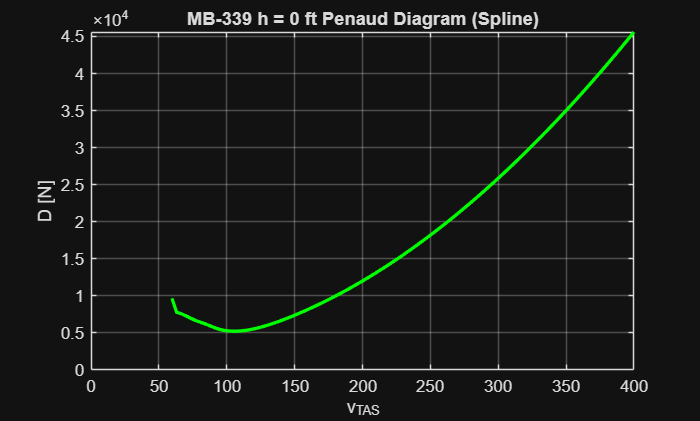

D_spline_h = @(v,rho) 1/2 * rho_0 * v.^2 * S .* spline(CL(1:idx_CL_max), ...
    CD(1:idx_CL_max),2*wing_load/rho_0./v.^2);


figure
plot(v_D_domain_h0,D_spline_h(v_D_domain_h0,rho_0),"g",LineWidth=2)
grid on
title("MB-339 h = 0 ft Penaud Diagram (Spline)")
xlabel('v_{TAS}')
ylabel("D [N]")
xlim([0, inf])
ylim([0, inf])

Note how the spline interpolation has a weird shape near stall velocity: not ideal!

### Quadratic interpolation

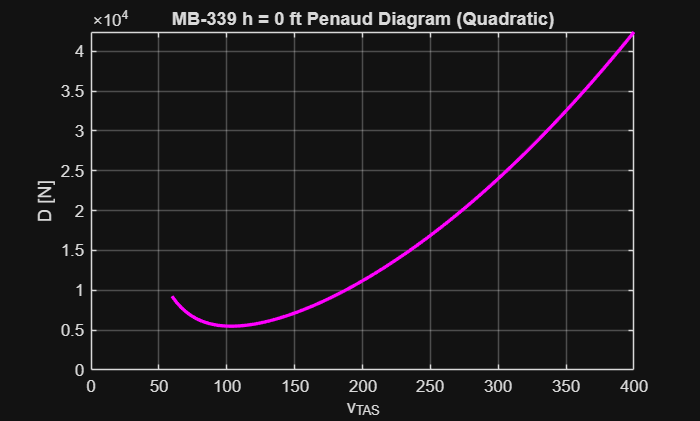

D_quadratic_h = @(v,rho) 1/2 * rho * v.^2 * S .* polyval(polyfit(CL(1:idx_CL_max), ...
    CD(1:idx_CL_max),2),2*wing_load/rho./v.^2);


figure
plot(v_D_domain_h0,D_quadratic_h(v_D_domain_h0,rho_0),"m",LineWidth=2)
grid on
title("MB-339 h = 0 ft Penaud Diagram (Quadratic)")
xlabel('v_{TAS}')
ylabel("D [N]")
xlim([0, inf])
ylim([0, inf])

### Analytical

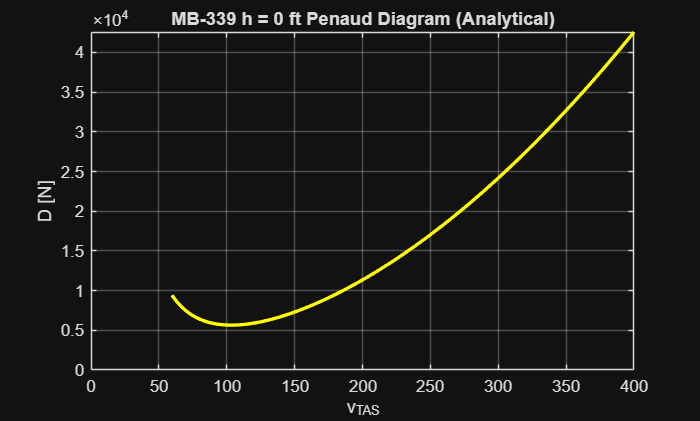

D_analytical_h = @(v,rho) 1/2 * rho * v.^2 * S .* ...
                (CD0 + k .* (2*wing_load / rho ./v.^2).^2);

figure
plot(v_D_domain_h0,D_analytical_h(v_D_domain_h0,rho_0),"y",LineWidth=2)
grid on
title("MB-339 h = 0 ft Penaud Diagram (Analytical)")
xlabel('v_{TAS}')
ylabel("D [N]")
xlim([0, inf])
ylim([0, inf])

### Comparison

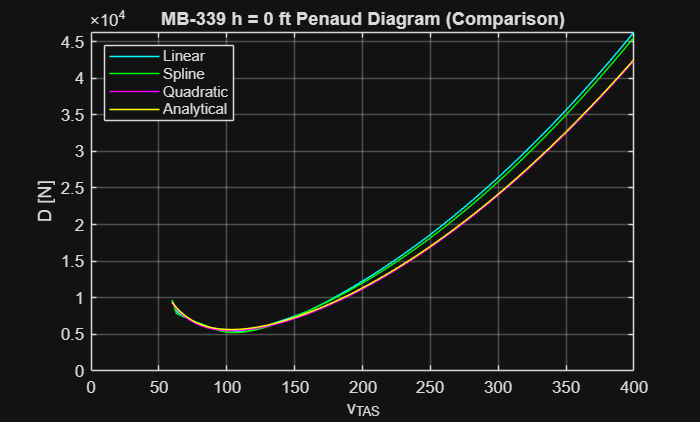

figure
plot(v_D_domain_h0,D_interp1_h(v_D_domain_h0),"c")
grid on
hold on
plot(v_D_domain_h0,D_spline_h(v_D_domain_h0),"g")
plot(v_D_domain_h0,D_quadratic_h(v_D_domain_h0,rho_0),"m")
plot(v_D_domain_h0,D_analytical_h(v_D_domain_h0,rho_0),"y")
title('MB-339 h = 0 ft Penaud Diagram (Comparison)')
xlabel('v_{TAS}')
ylabel("D [N]")
xlim([0, inf])
ylim([0, inf])
legend('Linear','Spline','Quadratic','Analytical',Location='northwest')

Note how quadratic and analytical diagrams are basically the same: from now on only analytical polar will be used!

### Altitude effect on analytical polar

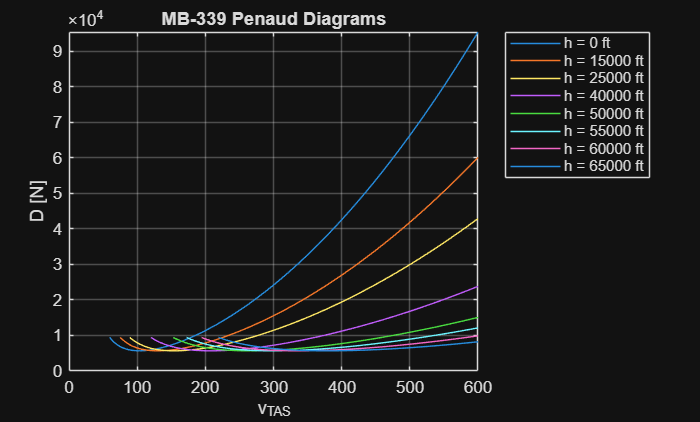

v_guess_h = 600;
v_stall_h = zeros(n,1);
v_D_domain_h = zeros(n,len);
D_h = zeros(n,len);

for i=1:n
    v_stall_h(i) = v_stall_h_fun(rho_h(i));
    v_D_domain_h(i,:) = linspace(v_stall_h(i),v_guess_h,len);
    D_h(i,:) = D_analytical_h(v_D_domain_h(i,:),rho_h(i)); 
end

figure
plot(v_D_domain_h.',D_h.')
grid on
title('MB-339 Penaud Diagrams')
xlabel('v_{TAS}')
ylabel("D [N]")
xlim([0, inf])
ylim([0, inf])
legendLabels = compose('h = %g ft', h); 
legend(legendLabels, 'Location', 'northeastoutside');

## SET (Specific Excess Thrust) and SEP (Specific Excess Power)

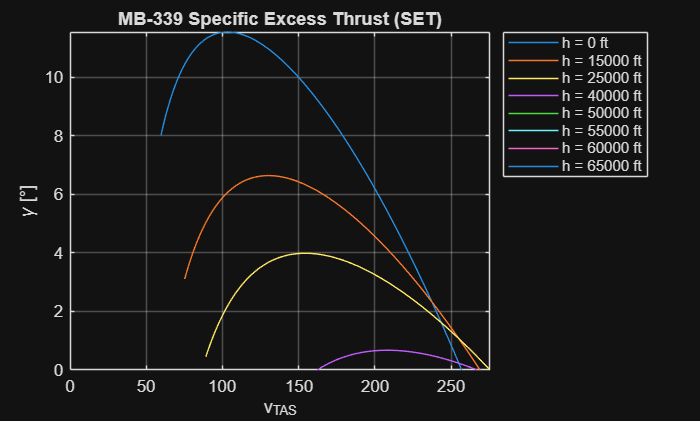

v_SET_SEP_domain_h = zeros(n,len);
SET_h = zeros(n,len);
SEP_h = zeros(n,len);

SET = @(T,D) (T-D) / W;
SEP = @(P_a,P_r) (P_a-P_r) / W;
g_fun = @(v,rho) D_quadratic_h(v,rho) - T_rho(rho);
opts = optimset('Display', 'off');

for i = 1:n
    v_max = fzero(@(v) g_fun(v,rho_h(i)), 400, opts);
    v_min = fzero(@(v) g_fun(v,rho_h(i)), 100, opts);
    if v_stall_h(i) > v_min
        v_min = v_stall_h(i);
    end
    v_SET_SEP_domain_h(i,:) = linspace(v_min, v_max, len);
    SET_h(i,:) = SET(T_rho(rho_h(i)),D_quadratic_h(v_SET_SEP_domain_h(i,:),rho_h(i)));
    SEP_h(i,:) = SET_h(i,:) .* v_SET_SEP_domain_h(i,:);
end

figure
plot(v_SET_SEP_domain_h.',rad2deg(SET_h.'))
grid on
title('MB-339 Specific Excess Thrust (SET)')
xlabel('v_{TAS}')
ylabel("\gamma [°]")
xlim([0, inf])
ylim([0, inf])
legendLabels = compose('h = %g ft', h); 
legend(legendLabels, 'Location', 'northeastoutside');

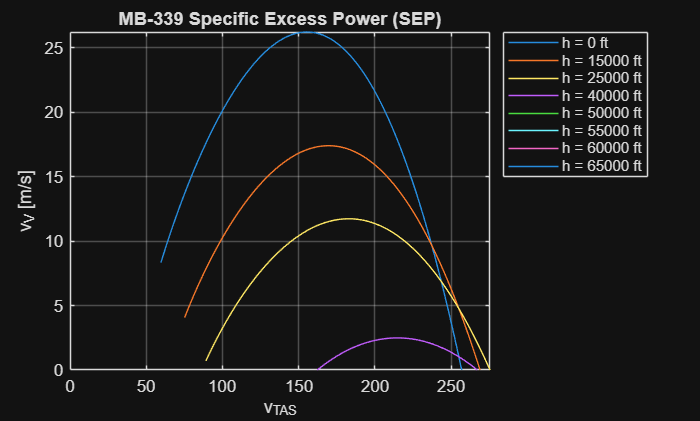

figure
plot(v_SET_SEP_domain_h.',SEP_h.')
grid on
title('MB-339 Specific Excess Power (SEP)')
xlabel('v_{TAS}')
ylabel("v_V [m/s]")
xlim([0, inf])
ylim([0, inf])
legendLabels = compose('h = %g ft', h); 
legend(legendLabels, 'Location', 'northeastoutside');

## FLIGHT ENVELOPE

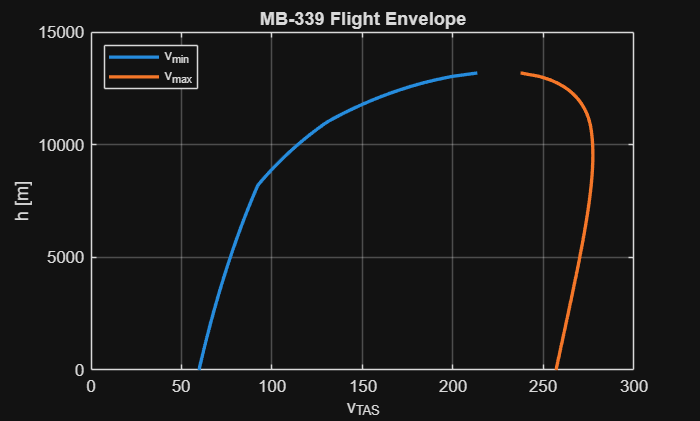

h_max = 15000;
h_envelope = linspace(0,h_max,len);
v_min_envelope = zeros(len,1);
v_max_envelope = zeros(len,1);
v_stall_envelope = zeros(len,1);
rho_envelope = zeros(len,1);
SET_envelope = zeros(n,len);
SEP_envelope = zeros(n,len);
v_envelope_domain = zeros(n,len);

for i = 1:len
    [~,~,~,rho_envelope(i)] = atmosisa(h_envelope(i));
    
    v_max_envelope(i) = fzero(@(v) g_fun(v,rho_envelope(i)), 300, opts);
    v_min_envelope(i) = fzero(@(v) g_fun(v,rho_envelope(i)), 100, opts);
    v_stall_envelope(i) = v_stall_h_fun(rho_envelope(i));
    
    if v_stall_envelope(i) > v_min_envelope(i)
        v_min_envelope(i) = v_stall_envelope(i);
    end
    
    v_envelope_domain(i,:) = linspace(v_min_envelope(i), v_max_envelope(i), len);
    SET_envelope(i,:) = SET(T_rho(rho_envelope(i)),D_quadratic_h(v_envelope_domain(i,:),rho_envelope(i)));
    SEP_envelope(i,:) = SET_envelope(i,:) .* v_envelope_domain(i,:);

end

figure
plot(v_min_envelope,h_envelope,LineWidth=2)
hold on
plot(v_max_envelope,h_envelope,LineWidth=2)
grid on
title('MB-339 Flight Envelope')
xlabel('v_{TAS}')
ylabel("h [m]")
xlim([0, 300])
ylim([0, h_max])
legend('v_{min}','v_{max}','Location','northwest')

## TIME TO CLIMB

Quasi-steady and unsteady approach.

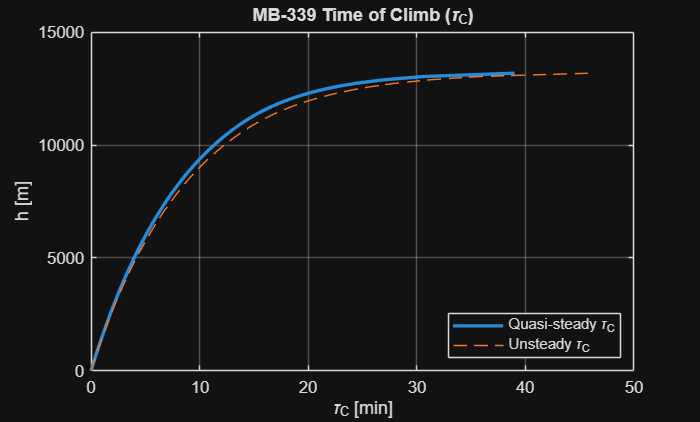

g = 9.81;

SEP_max_envelope = zeros(len,1);
v_best_climb = zeros(len,1);
for i = 1:len
    [SEP_max_envelope(i), idx] = max(SEP_envelope(i,:));
    v_best_climb(i) = v_envelope_domain(i,idx);
end

delta_t_i_quasi_steady = zeros(len,1);
delta_t_i_unsteady = zeros(len,1);

for i = 2:len
    delta_h_tmp = h_envelope(i) - h_envelope(i-1);
    SEP_avg = (SEP_max_envelope(i) + SEP_max_envelope(i-1)) / 2;
    v_avg = (v_best_climb(i) + v_best_climb(i-1)) / 2;
    dv_dh_tmp = (v_best_climb(i) - v_best_climb(i-1)) / delta_h_tmp;

    delta_t_i_quasi_steady(i) = delta_t_i_quasi_steady(i-1) + delta_h_tmp / SEP_avg;

    accel_factor = 1 + (v_avg/g) * dv_dh_tmp;
    delta_t_i_unsteady(i) = delta_t_i_unsteady(i-1) + delta_h_tmp / SEP_avg * accel_factor;
end

figure
plot(delta_t_i_quasi_steady./60, h_envelope, LineWidth=2)
hold on
grid on
title('MB-339 Time of Climb (\tau_C)')
plot(delta_t_i_unsteady./60, h_envelope, "LineStyle","--")
xlim([0 50])
ylim([0 h_max])
legend('Quasi-steady \tau_C','Unsteady \tau_C','Location','southeast')
xlabel('\tau_C [min]')
ylabel('h [m]')